# Second-Order Mass-Spring-Damper

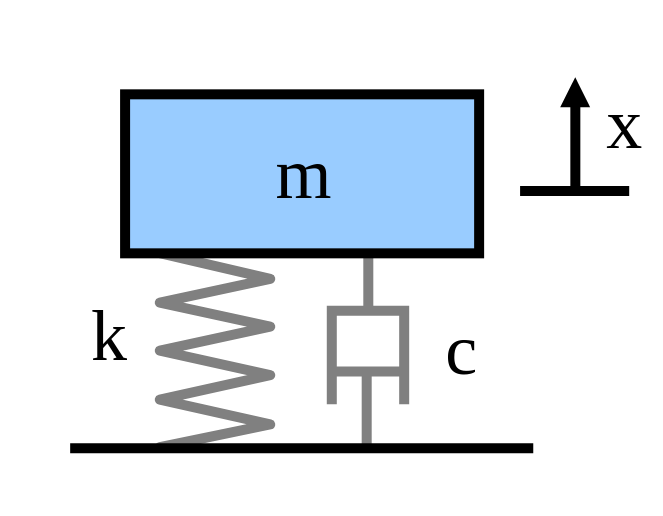

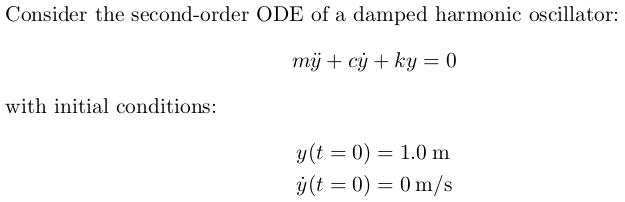

## Define the State vector

## Formulate problem in state-space form

## Implement the ODE with a rate function

function dxxdt = msd(t, xx)
    % Unpack - depends on state vector definition!
    y = xx(1);
    v = xx(2);
    % Parameter values
    m = 1; % kg
    c = 0.2;  % N/(m/s)
    k = 5; % N/m
    % ODE
    dydt = v;
    dvdt = -c/m*v - k/m*y;
    % Pack - following state vector definition
    dxxdt(1) = dydt;
    dxxdt(2) = dvdt;
    % Make sure it is a column vector
    dxxdt = dxxdt(:);
end

## Apply solver

% Define initial conditions - following state vector definition.
xx0 = [1; 0];
% Time span
tspan = [0 10];
[tt, xx] = ode45(@msd, tspan, xx0);
size(tt)
size(xx)

## Verify

figure;
clf;
plot(tt, xx)

What would be the correct legend?

What are the units?

How would we plot just displacement?